# Sample 11-3

## 画像ノイズ除去

正規方程式

画像処理特論

村松 正吾 

動作確認: MATLAB R2020a

## Image denoising

Normal equation

Advanced Topics in Image Processing

Shogo MURAMATSU

Verified: MATLAB R2020a

### 準備

(Preparation)

close all

## 問題設定

(Problem setting)

    
$$\hat{\mathbf{s}}=\arg\min_{\mathbf{s}}\frac{1}{2}\|\mathbf{v}-\mathbf{Ds}\|_2^2+\frac{\lambda}{2}\|\mathbf{s}\|_2^2$$


- 
$$\mathbf{D} = \left(\begin{array}{cc} \frac{2}{3} & \frac{1}{3}\end{array}\right)\colon\quad \mathbb{R}^2\rightarrow\mathbb{R}^1$$


- 
$$\mathbf{v}=\frac{1}{2}\in\mathbb{R}^1$$


- 
$$\lambda\in[0,\infty)$$


- 
$$\mathbf{s}\in\mathbb{R}^2$$


D = [2 1]/3;
v = 0.5;

### 関数プロット

(Function plot)

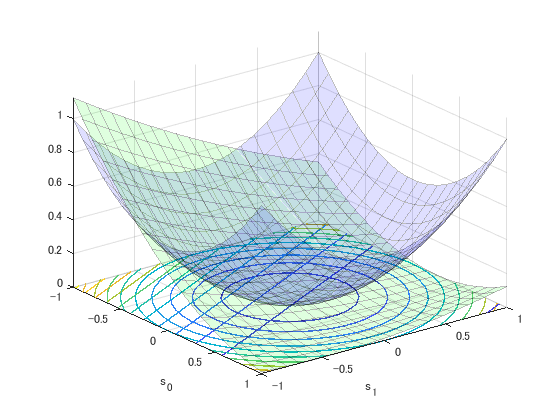

% Function settings
f = @(s0,s1) 0.5*(v-(D(1)*s0+D(2)*s1)).^2;
g = @(s0,s1) 0.5*(s0.^2+s1.^2);
% Variable settings
s0 = linspace(-1,1,20);
s1 = linspace(-1,1,20);
[S0,S1] = ndgrid(s0,s1);
% Evaluation
F = f(S0,S1);
G = g(S0,S1);
% Surfc plot of the fidelity f()
hf = surfc(s0,s1,F);
hf(1).FaceAlpha = 0.125;
hf(1).FaceColor = 'green';
hf(1).EdgeAlpha = 0.25;
hf(2).LineWidth = 1;
set(gca,'YDir','reverse');
hold on
% Surfc plot of the regularizer g()
hg = surfc(s0,s1,G);
hg(1).FaceAlpha = 0.125;
hg(1).FaceColor = 'blue';
hg(1).EdgeAlpha = 0.25;
hg(2).LineWidth = 1;
xlabel('s_1')
ylabel('s_0')

### 正規方程式とその解

(Normal Equation and its Solution)

正規方程式 (Normal equation)

        
$$(\mathbf{D}^T\mathbf{D}+\lambda\mathbf{I})\mathbf{s}=\mathbf{D}^T\mathbf{v}$$


解 (Solution)

        
$$\hat{\mathbf{s}}=(\mathbf{D}^T\mathbf{D}+\lambda\mathbf{I})^{-1}\mathbf{D}^T\mathbf{v}$$


% Evaluation values for λ
lmdset = logspace(-1,1,3);
idx = 1;
s = zeros(size(D,2),length((lmdset)));
for lambda = lmdset
    s(:,idx) = (D.'*D+lambda*eye(2))\(D.'*v); 
    ht = text(s(2,idx)+.1,s(1,idx)-.2,['\lambda=' num2str(lambda)]);
    ht.FontSize = 12;
    idx = idx+1;
end

解のプロット (Solution plot)

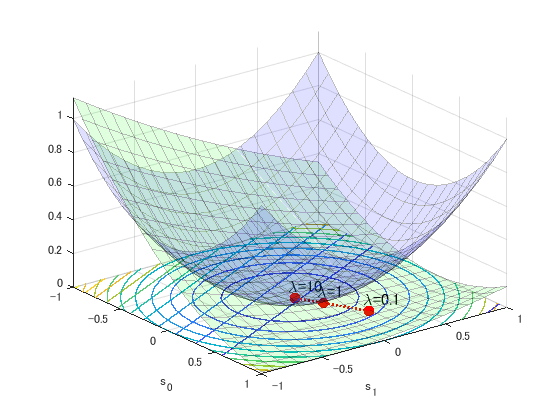

hp = plot(s(2,:),s(1,:));
hp.Marker = 'o';
hp.MarkerSize = 6;
hp.MarkerEdgeColor = 'r';
hp.MarkerFaceColor = 'r';
hp.Color = 'r';
hp.LineWidth = 2;
hp.LineStyle = ':';
hp.Visible = true;
hold off

© Copyright, Shogo MURAMATSU, All rights reserved.